## **Import data**

% all 12 months data is imported in a file datastore
raw_data= fileDatastore('D:\asus\15.Cody\Data Science\3. Predictive Modeling and Machine Learning\Taxi Data\Taxi Data\data',"ReadFcn",@importTaxiDataWithoutCleaning,'UniformRead',true)

raw_data =   FileDatastore with properties:

                       Files: {
                              ' ...\Taxi Data\Taxi Data\data\yellow_tripdata_2015-01.csv';
                              ' ...\Taxi Data\Taxi Data\data\yellow_tripdata_2015-02.csv';
                              ' ...\Taxi Data\Taxi Data\data\yellow_tripdata_2015-03.csv'
                               ... and 9 more
                              }
                     Folders: {
                              ' ...\3. Predictive Modeling and Machine Learning\Taxi Data\Taxi Data\data'
                              }
                 UniformRead: 1
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @importTaxiDataWithoutCleaning
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "f

data = 2922266×19 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________    __________    ___________    ____

data=readall(raw_data)

data = 2922266×19 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________    __________    ___________    ____

The data contains 2,922,266 entries with 19 feature variables.

## **Exploratory Data Analysis (EDA)**

summary(data)

Variables:

    Vendor: 2922266×1 categorical

        Values:

            1    1.3876e+06
            2    1.5347e+06

    PickupTime: 2922266×1 datetime

        Values:

            Min       2015-01-01 00:00:43
            Median    2015-06-20 18:21:55
            Max       2015-12-31 23:59:59

    DropoffTime: 2922266×1 datetime

        Values:

            Min       2015-01-01 00:04:02
            Median    2015-06-20 18:35:14
            Max       2016-01-01 22:10:58

    Passengers: 2922266×1 double

        Values:

            Min          0    
            Median       1    
            Max          9    

    Distance: 2922266×1 double

        Values:

            Min               0
            Median         1.71
            Max       1.468e+07

    PickupLon: 2922266×1 double

        Values:

            Min        -171.8 
            Median    -73.982 
            M

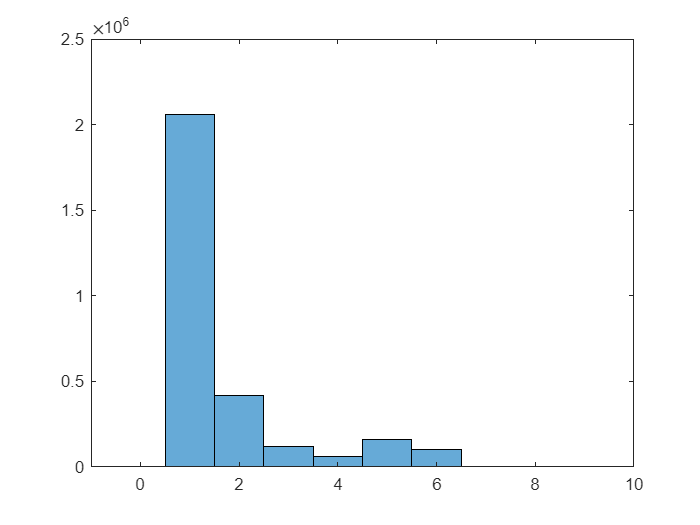

histogram(data.Passengers)

Most of the rides were with single passengers.

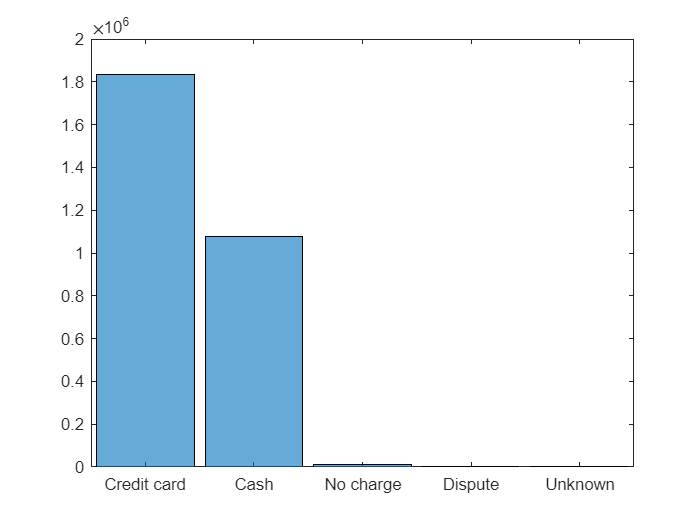

histogram(data.PayType)

## **Adding taxi zones **

data_2=addTaxiZones(data)

data_2 = 2922266×23 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone         
    ______    ___________________    ___________________    __________    ________    _________    _________

4 new feature variables are added using the shapefile information ("TaxiZones.shp" file).

## **Converting zones to taxis**

**Adding pick-up regions**

% creating 2 new feature variables
data_2.pickup_region= data_2.PickupZone;
data_2.drop_region= data_2.DropoffZone;

% import the "Taxi Regions and Zones.csv" file as 'regions'
regions

regions = 19×6 table
            LowerManhattan                         Midtown                      UpperEastSide              UpperWestSide          JFKAirport       LaGuardiaAirport  
    _______________________________    ________________________________    _______________________    _______________________    _____________    ___________________

    "Alphabet City"                    "Clinton East"                      "Upper East Side North"    "Upper West Side North"    "JFK Airport"    "LaGuardia Airport"
    "Battery Park"                     "Clinton West"                      "Upper East Side South"    "Upper West Side South"    ""               ""                 
    "Battery Park City"                "Midtown Center"                    "Yorkville East"           "Lincoln

% creating another copy
data_3=data_2;

% convert the variable to string
data_3.pickup_region=string(data_3.pickup_region)

data_3 = 2922266×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone                      pickup_region                      drop_region         
    ______    ___________________    ___________________    ___

% We want to group all these sub-regions into 6 overall region.
r1=replace(data_3.pickup_region, regions.LowerManhattan, "Lower Manhattan");
data_3.pickup_region=r1;

r2=replace(data_3.pickup_region,regions.Midtown, "Midtown");
data_3.pickup_region=r2;

r3=replace(data_3.pickup_region, regions.UpperEastSide(1:7), "Upper East Side");
data_3.pickup_region=r3;

r4=replace(data_3.pickup_region, regions.UpperWestSide(1:6), "Upper West Side");
data_3.pickup_region=r4;

data_3

data_3 = 2922266×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone                pickup_region                drop_region         
    ______    ___________________    ___________________    __________

data_4=data_3;
data_4.pickup_region=categorical(data_4.pickup_region)

data_4 = 2922266×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone               pickup_region               drop_region         
    ______    ___________________    ___________________    __________

summary(data_4.pickup_region)

     Allerton/Pelham Gardens             13 
     Arrochar/Fort Wadsworth              2 
     Astoria                           6167 
     Astoria Park                        49 
     Auburndale                           9 
     Baisley Park                       414 
     Bath Beach                          18 
     Bay Ridge                          133 
     Bay Terrace/Fort Totten              7 
     Bayside                             19 
     Bedford                           1331 
     Bedford Park                        42 
     Bellerose                           12 
     Belmont                             36 
     Bensonhurst East                    31 
     Bensonhurst West                    54 
     

So, there are many areas that did not fall into the 6 specified regions. We will take care of those later.

**Adding Drop-off Regions**

data_4.drop_region=string(data_4.drop_region);

r1=replace(data_4.drop_region, regions.LowerManhattan,"Lower Manhattan");
data_4.drop_region=r1;

r2=replace(data_4.drop_region, regions.Midtown, "Midtown");
data_4.drop_region=r2;

r3=replace(data_4.drop_region, regions.UpperEastSide(1:7),"Upper East Side");
data_4.drop_region=r3;

r4=replace(data_4.drop_region, regions.UpperWestSide(1:6),"Upper West Side");
data_4.drop_region=r4;

data_4.drop_region=categorical(data_4.drop_region)

data_4 = 2922266×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone               pickup_region              drop_region        
    ______    ___________________    ___________________    __________

summary(data_4.drop_region)

     Allerton/Pelham Gardens            170 
     Arden Heights                       16 
     Arrochar/Fort Wadsworth             63 
     Astoria                          15209 
     Astoria Park                        77 
     Auburndale                         176 
     Baisley Park                       837 
     Bath Beach                         249 
     Bay Ridge                         2546 
     Bay Terrace/Fort Totten            217 
     Bayside                            388 
     Bedford                           6192 
     Bedford Park                       468 
     Bellerose                          143 
     Belmont                            296 
     Bensonhurst East                   397 
     

## Data Preprocessing

dp = data_4;

%invalid ratecode
dp2 = dp(dp.RateCode ~= "99", :); 

%invalid location
dp3 = standardizeMissing(dp2, 0, "DataVariables", ["PickupLat","PickupLon","DropoffLat","DropoffLon"]);
dp3 = rmmissing(dp3, "DataVariables", ["PickupLat","PickupLon","DropoffLat","DropoffLon"]);

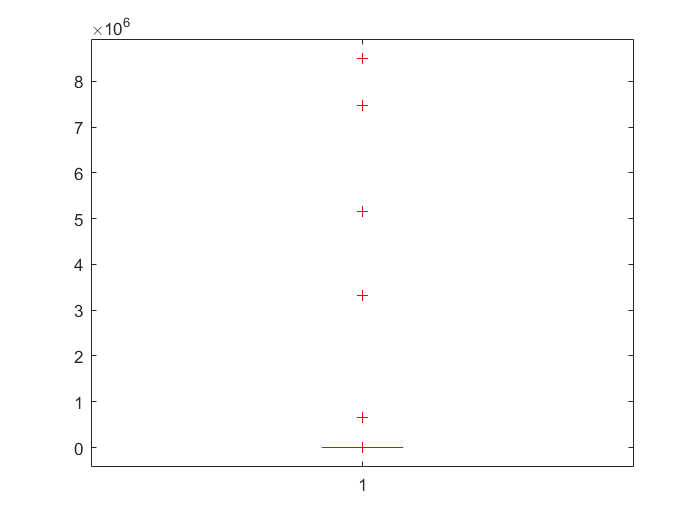

%passengers
dp4=dp3(dp3.Passengers>0,:);
boxplot(dp4.Distance)

prctile(dp4.Distance,[0,99])

ans =          0   18.6000


dp5=dp4(dp4.Distance>0,:);
prctile(dp5.Distance,[0,99])

ans =     0.0100   18.6000


prctile(dp5.Distance,[0,99.9])

ans =     0.0100   24.5300


prctile(dp5.Distance,[0,99.99])

ans =     0.0100   40.5000



dp6=rmoutliers(dp5,"percentiles",[0,99.99],"DataVariables","Distance")

dp6 = 2858743×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone               pickup_region              drop_region        
    ______    ___________________    ___________________    __________   

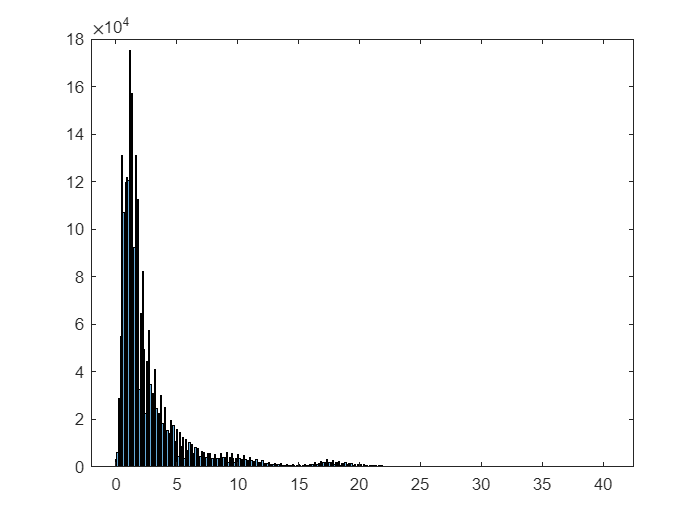

histogram(dp6.Distance)

% fare
prctile(dp6.Fare,[0,99])

ans =   -118    52


sum(dp6.Fare<=0)

ans = 1189

sum(dp6.Fare<=2.5)

ans = 5876


dp7=dp6(dp6.Fare>0,:);

prctile(dp7.Fare,[0,99.9])

ans =     0.0100   76.0000


prctile(dp7.Fare,[0,99.99])

ans =     0.0100  140.0000


sum(dp7.Fare>140)

ans = 270

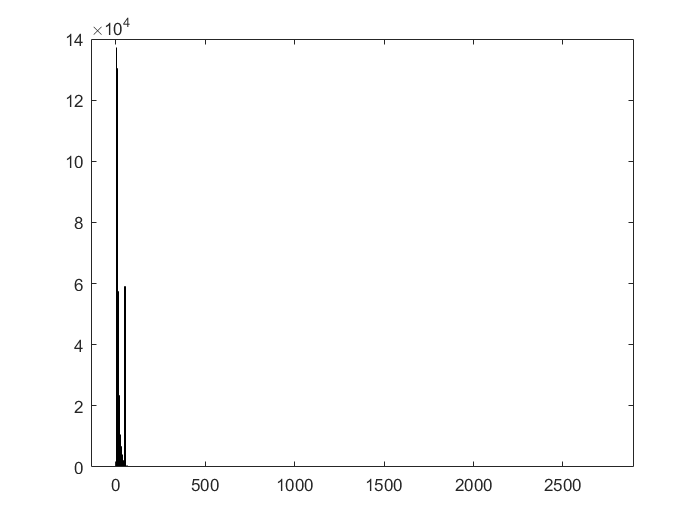

histogram(dp7.Fare)


dp8=rmoutliers(dp7,"percentiles",[0,99.99],"DataVariables","Fare")

dp8 = 2857284×25 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone               pickup_region              drop_region        
    ______    ___________________    ___________________    __________   

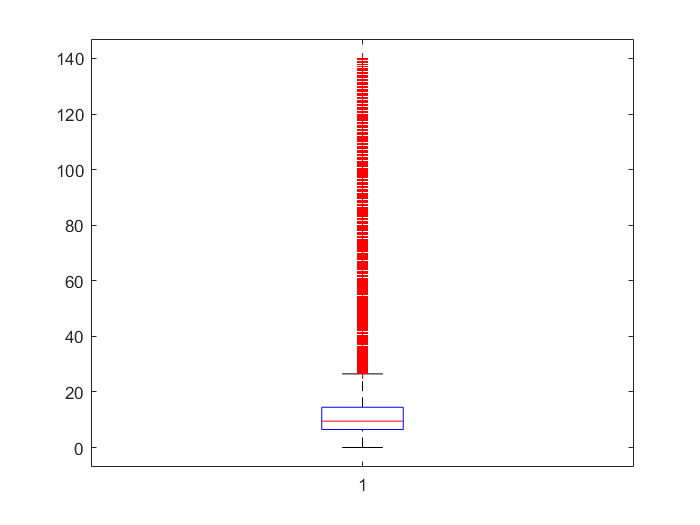


boxplot(dp8.Fare)


dp9=dp8(dp8.Fare>=2.5,:);

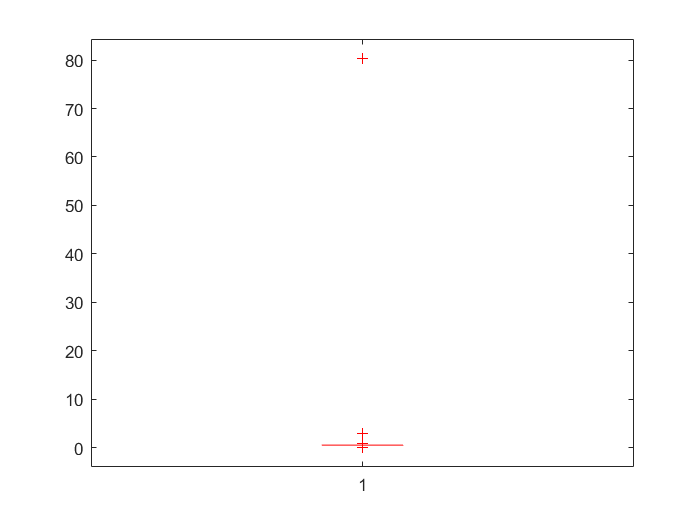

% extra charge
dp9=dp9(dp9.ExtraCharge>=0,:);
dp9=dp9(dp9.Tax>=0,:);
dp9=dp9(dp9.Tip>=0,:);
dp9=dp9(dp9.Tolls>=0,:);
dp9=dp9(dp9.ImpSurcharge>=0,:);
dp10=dp9(dp9.TotalCharge>=0,:);

boxplot(dp10.Tax)

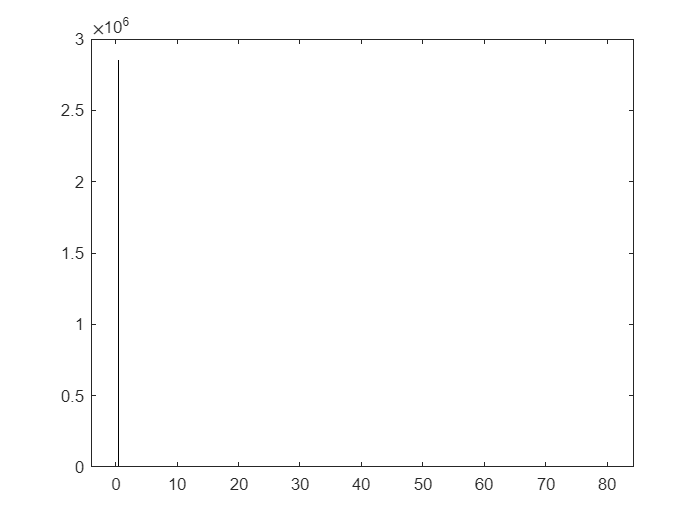

histogram(dp10.Tax)

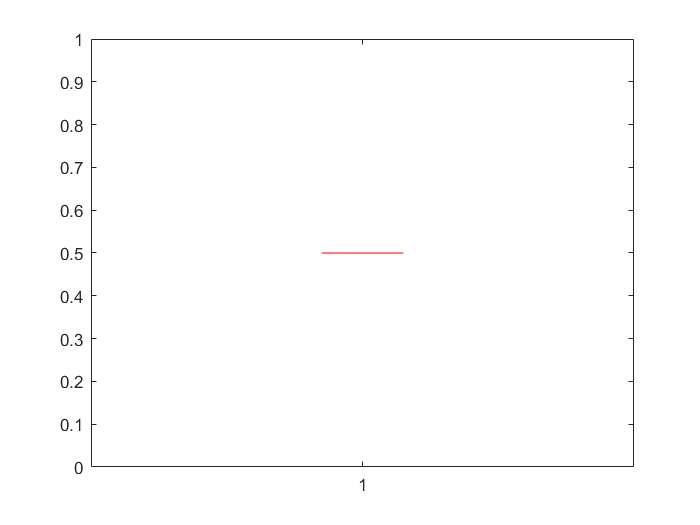


dp11 = dp10(abs(dp10.ImpSurcharge-0.3) < 0.01, :); 
dp11 = dp11(abs(dp11.Tax-0.5) < 0.01, :); 
dp11 = dp11(abs(dp11.Fare + dp11.ExtraCharge + dp11.Tax + dp11.Tip + dp11.Tolls + dp11.ImpSurcharge - dp11.TotalCharge) < 0.01, :);

boxplot(dp11.Tax)

% fare distance ratio
x=dp11.Fare./dp11.Distance;
prctile(x,[0,99])

ans =     0.0712   15.1515


prctile(x,[0,99.99])

ans =     0.0712  520.0000


sum(x>520)

ans = 269


dp12=dp11(x<=520,:);

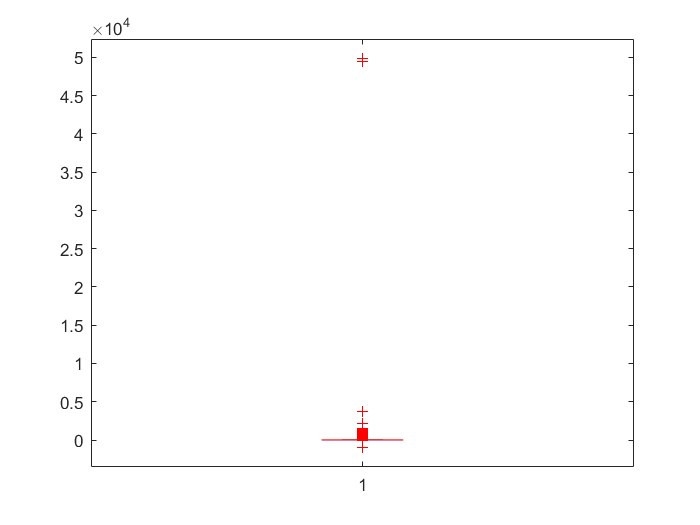

df = addDuration(dp12); % minutes
df = addAveSpeed(df); % mph

boxplot(df.Duration)

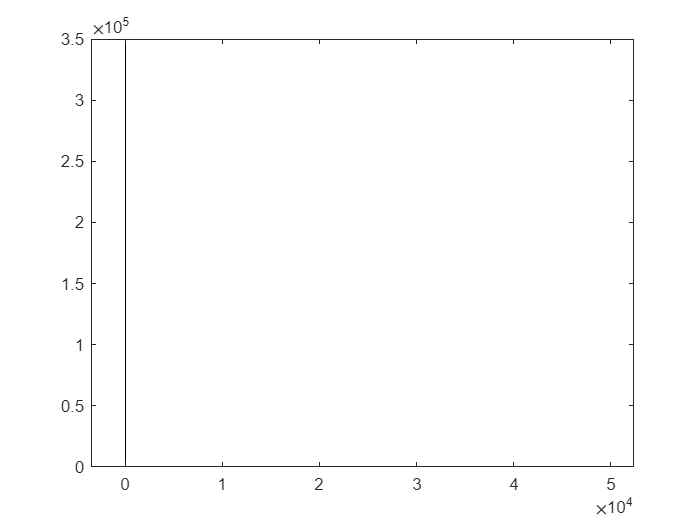

histogram(df.Duration)

prctile(df.Duration,[0,99])

ans =  -985.5000   56.2667


prctile(df.Duration,[0,99.5])

ans =  -985.5000   66.8667


sum(df.Duration<=0)

ans = 139


df2=df(df.Duration>=1 & df.Duration<120,:)

df2 = 2824737×27 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone               pickup_region              drop_region            Duration    AveSpeed
    ______    ___________________    ____


df2=df2(df2.AveSpeed>=0.1 & df2.AveSpeed<100,:);
df2=df2(df2.TotalCharge>=0.5 & df2.TotalCharge<=120,:);
df3=df2(df2.Tolls<=20,:);

timeofday(df3.PickupTime);

hour(df3.PickupTime(1:6));

%writetable(df3,'prepared_dataset_01.csv')

% Only keep trips that begin and end inside the region of interest.

lat = [40.5612 40.9637]; 
lon = [-74.1923 -73.5982]; 

inROI = inpolygon(df3.PickupLat,df3.PickupLon, lat([1 2 2 1]),lon([1 1 2 2])) ...
    & inpolygon(df3.DropoffLat,df3.DropoffLon, lat([1 2 2 1]),lon([1 1 2 2]));


df5 = df3(inROI,:);

### **Hourly data**

df5.hourly_data= dateshift(df5.PickupTime,"start","hour");

df5.hourly_data_dropoff= dateshift(df5.DropoffTime,"start","hour");

df6=df5(:,["PickupTime","DropoffTime","Distance","Fare","ExtraCharge","Tax","Tip","Tolls","ImpSurcharge","TotalCharge","pickup_region","drop_region","Duration","AveSpeed","hourly_data","hourly_data_dropoff"])

df6 = 2823681×16 table
        PickupTime             DropoffTime        Distance    Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge      pickup_region              drop_region            Duration    AveSpeed        hourly_data        hourly_data_dropoff
    ___________________    ___________________    ________    ____    ___________    ___    ____    _____    ____________    ___________    _________________    ___________________________    ________    ________


%writetable(df6,'short_dataset.csv')

### Removing Other Regions

ds=df6;

regions=["Lower Manhattan","Midtown","Upper East Side","Upper West Side","JFK Airport","LaGuardia Airport"];

ds2=ds((ds.pickup_region==regions(1) | ds.pickup_region==regions(2) | ds.pickup_region==regions(3) | ds.pickup_region==regions(4)|ds.pickup_region==regions(5) | ds.pickup_region==regions(6)),:)

ds2 = 2627262×16 table
        PickupTime             DropoffTime        Distance    Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge      pickup_region              drop_region            Duration    AveSpeed        hourly_data        hourly_data_dropoff
    ___________________    ___________________    ________    ____    ___________    ___    ____    _____    ____________    ___________    _________________    ___________________________    ________    ________

unique(ds2.pickup_region)

ans = 6×1 categorical array
     JFK Airport 
     LaGuardia Airport 
     Lower Manhattan 
     Midtown 
     Upper East Side 
     Upper West Side 



ds3=ds2((ds2.drop_region==regions(1) | ds2.drop_region==regions(2) | ds2.drop_region==regions(3) | ds2.drop_region==regions(4)|ds2.drop_region==regions(5) | ds2.drop_region==regions(6)),:)

ds3 = 2292216×16 table
        PickupTime             DropoffTime        Distance    Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge      pickup_region        drop_region      Duration    AveSpeed        hourly_data        hourly_data_dropoff
    ___________________    ___________________    ________    ____    ___________    ___    ____    _____    ____________    ___________    _________________    _______________    ________    ________    ________

unique(ds3.drop_region)

ans = 6×1 categorical array
     JFK Airport 
     LaGuardia Airport 
     Lower Manhattan 
     Midtown 
     Upper East Side 
     Upper West Side 


### Grouping

gp=groupsummary(ds3,["pickup_region","hourly_data"],"mean",["Duration","Distance","Fare"])

gp = 48734×6 table
    pickup_region        hourly_data        GroupCount    mean_Duration    mean_Distance    mean_Fare
    _____________    ___________________    __________    _____________    _____________    _________

     JFK Airport     2015-01-01 05:00:00        1                36            19.93           52    
     JFK Airport     2015-01-01 07:00:00        1            23.733            19.47           52    
     JFK Airport     2015-01-01 09:00:00        1              23.7            17.27           52    
     JFK Airport     2015-01-01 11:00:00        1              36.3            19.23           52    
     JFK Airport     2015-01-01 12:00:00        1              24.3            16.98           52    
     JFK Airport     2015-01-01 13:00:00        2            2

gp.Properties.VariableNames(3)="pickup_count"

gp = 48734×6 table
    pickup_region        hourly_data        pickup_count    mean_Duration    mean_Distance    mean_Fare
    _____________    ___________________    ____________    _____________    _____________    _________

     JFK Airport     2015-01-01 05:00:00         1                 36            19.93           52    
     JFK Airport     2015-01-01 07:00:00         1             23.733            19.47           52    
     JFK Airport     2015-01-01 09:00:00         1               23.7            17.27           52    
     JFK Airport     2015-01-01 11:00:00         1               36.3            19.23           52    
     JFK Airport     2015-01-01 12:00:00         1               24.3            16.98           52    
     JFK Airport     2015-01-01 13:00:00        


gd=groupsummary(ds3,["drop_region","hourly_data_dropoff"],"mean",["Duration","Distance","Fare"])

gd = 47468×6 table
    drop_region    hourly_data_dropoff    GroupCount    mean_Duration    mean_Distance    mean_Fare
    ___________    ___________________    __________    _____________    _____________    _________

    JFK Airport    2015-01-01 04:00:00        1              31.2            18.41            52   
    JFK Airport    2015-01-01 06:00:00        1             23.95            16.38            52   
    JFK Airport    2015-01-01 07:00:00        2            22.133           16.815            52   
    JFK Airport    2015-01-01 08:00:00        1            29.083            18.65            52   
    JFK Airport    2015-01-01 09:00:00        3            25.117           17.963            52   
    JFK Airport    2015-01-01 10:00:00        2             28.85           

gd.Properties.VariableNames(3)="drop_count"

gd = 47468×6 table
    drop_region    hourly_data_dropoff    drop_count    mean_Duration    mean_Distance    mean_Fare
    ___________    ___________________    __________    _____________    _____________    _________

    JFK Airport    2015-01-01 04:00:00        1              31.2            18.41            52   
    JFK Airport    2015-01-01 06:00:00        1             23.95            16.38            52   
    JFK Airport    2015-01-01 07:00:00        2            22.133           16.815            52   
    JFK Airport    2015-01-01 08:00:00        1            29.083            18.65            52   
    JFK Airport    2015-01-01 09:00:00        3            25.117           17.963            52   
    JFK Airport    2015-01-01 10:00:00        2             28.85           


sum(ismissing(gd))

ans =      0     0     0     0     0     0


sum(ismissing(gp))

ans =      0     0     0     0     0     0



gp.Properties.VariableNames(1)="region"

gp = 48734×6 table
      region           hourly_data        pickup_count    mean_Duration    mean_Distance    mean_Fare
    ___________    ___________________    ____________    _____________    _____________    _________

    JFK Airport    2015-01-01 05:00:00         1                 36            19.93           52    
    JFK Airport    2015-01-01 07:00:00         1             23.733            19.47           52    
    JFK Airport    2015-01-01 09:00:00         1               23.7            17.27           52    
    JFK Airport    2015-01-01 11:00:00         1               36.3            19.23           52    
    JFK Airport    2015-01-01 12:00:00         1               24.3            16.98           52    
    JFK Airport    2015-01-01 13:00:00         2             2

gd.Properties.VariableNames(1)="region"

gd = 47468×6 table
      region       hourly_data_dropoff    drop_count    mean_Duration    mean_Distance    mean_Fare
    ___________    ___________________    __________    _____________    _____________    _________

    JFK Airport    2015-01-01 04:00:00        1              31.2            18.41            52   
    JFK Airport    2015-01-01 06:00:00        1             23.95            16.38            52   
    JFK Airport    2015-01-01 07:00:00        2            22.133           16.815            52   
    JFK Airport    2015-01-01 08:00:00        1            29.083            18.65            52   
    JFK Airport    2015-01-01 09:00:00        3            25.117           17.963            52   
    JFK Airport    2015-01-01 10:00:00        2             28.85           

gd.Properties.VariableNames(2)="hourly_data"

gd = 47468×6 table
      region           hourly_data        drop_count    mean_Duration    mean_Distance    mean_Fare
    ___________    ___________________    __________    _____________    _____________    _________

    JFK Airport    2015-01-01 04:00:00        1              31.2            18.41            52   
    JFK Airport    2015-01-01 06:00:00        1             23.95            16.38            52   
    JFK Airport    2015-01-01 07:00:00        2            22.133           16.815            52   
    JFK Airport    2015-01-01 08:00:00        1            29.083            18.65            52   
    JFK Airport    2015-01-01 09:00:00        3            25.117           17.963            52   
    JFK Airport    2015-01-01 10:00:00        2             28.85           

### Joining

dj= outerjoin(gp,gd,"Keys",["region","hourly_data"]);

dj_2= outerjoin(gp,gd,"Keys",["region","hourly_data"],"MergeKeys",true);

%Data Missing
sum(ismissing(dj_2))

ans =            0           0        1902        1902        1902        1902        3168        3168        3168        3168



%dj_3=fillmissing(dj_2,"constant",0)

dj_3=fillmissing(dj_2,"constant",0,'DataVariables',@isnumeric);

%Combining

dj_3.netpickups= dj_3.pickup_count- dj_3.drop_count;

dj_3.avg_duration=(dj_3.mean_Duration_gd + dj_3.mean_Duration_gp)/2;

dj_3.avg_distance=(dj_3.mean_Distance_gd + dj_3.mean_Distance_gp)/2;

dj_3.avg_fare=(dj_3.mean_Fare_gd + dj_3.mean_Fare_gp)/2;

dj_3

dj_3 = 50636×14 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________    ____________    ________

    JFK Airport    2015

### Train-test split

dj_4=dj_3;

rng(1)
partition=cvpartition(height(dj_4),"HoldOut",0.2)

partition = Hold-out cross validation partition
   NumObservations: 50636
       NumTestSets: 1
         TrainSize: 40509
          TestSize: 10127


train_idx=training(partition);
test_idx=test(partition);

train_data= dj_4(train_idx,:);
test_data = dj_4 (test_idx,:);

### Generating Response Variable

train_data.demand= discretize(train_data.netpickups,[-inf,0,15,inf],"categorical",["low","medium","high"])

train_data = 40509×15 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare    demand
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________    ____________    ________<

test_data.demand= discretize(test_data.netpickups,[-inf,0,15,inf],"categorical",["low","medium","high"])

test_data = 10127×15 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare    demand
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________    ____________    ________</

### Summary Statistics

groupsummary(train_data,"demand")

ans = 3×2 table
    demand    GroupCount
    ______    __________

    low         18037   
    medium      19236   
    high         3236   



groupsummary(test_data,"demand")

ans = 3×2 table
    demand    GroupCount
    ______    __________

    low          4414   
    medium       4916   
    high          797   



groupsummary(train_data,["demand","region"])

ans = 17×3 table
    demand         region          GroupCount
    ______    _________________    __________

    low       JFK Airport             1795   
    low       LaGuardia Airport       2173   
    low       Lower Manhattan         3348   
    low       Midtown                 3217   
    low       Upper East Side         3963   
    low       Upper West Side         3541   
    medium    JFK Airport             4536   
    medium    LaGuardia Airport       3944   
    medium    Lower Manhattan         3061   
    medium    Midtown                 2476   
    medium    Upper East Side         2239   
    medium    Upper West Side         2980   
    high      LaGuardia Airport         79   
    high      Lower Manhattan          588   
    high      Midtown                 1299   
    high      Upper East Side          797   



groupsummary(test_data,["demand","region"])

ans = 17×3 table
    demand         region          GroupCount
    ______    _________________    __________

    low       JFK Airport              487   
    low       LaGuardia Airport        499   
    low       Lower Manhattan          816   
    low       Midtown                  792   
    low       Upper East Side          944   
    low       Upper West Side          876   
    medium    JFK Airport             1144   
    medium    LaGuardia Airport        965   
    medium    Lower Manhattan          802   
    medium    Midtown                  665   
    medium    Upper East Side          597   
    medium    Upper West Side          743   
    high      LaGuardia Airport         12   
    high      Lower Manhattan          139   
    high      Midtown                  308   
    high      Upper East Side          212   


### Feature Creation

df=dj_4;

[~,df.DayOfWeek] = weekday(df.hourly_data,"long")

df = 50636×15 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare    DayOfWeek
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________    ____________    ________


df.DayOfWeek = categorical(cellstr(df.DayOfWeek));

x=df.hourly_data(26)

x = datetime
   2015-01-02 06:00:00


x2=datevec(x)

x2 =         2015           1           2           6           0           0


x3=datenum(x2(1:3))

x3 = 735966

day = x3 - datenum(x2(1), 1,0)

day = 2


df=adddayofyear(df)

df = 50636×16 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare    DayOfWeek    dayofyear
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________    ____________


df.demand= discretize(df.netpickups,[-inf,0,15,inf],"categorical",["low","medium","high"])

df = 50636×17 table
      region           hourly_data        pickup_count    mean_Duration_gp    mean_Distance_gp    mean_Fare_gp    drop_count    mean_Duration_gd    mean_Distance_gd    mean_Fare_gd    netpickups    avg_duration    avg_distance    avg_fare    DayOfWeek    dayofyear    demand
    ___________    ___________________    ____________    ________________    ________________    ____________    __________    ________________    ________________    ____________    __________    ____________  

### Feature Selection


%heatmap(df.demand,df.DayOfWeek)

crosstab(df.demand,df.DayOfWeek)

ans =         3225        3157        3142        3453        3272        3087        3115
        3405        3516        3584        3305        3436        3462        3444
         620         571         482         428         642         645         645



[a,chi2,p]=crosstab(df.demand,df.DayOfWeek)

a =         3225        3157        3142        3453        3272        3087        3115
        3405        3516        3584        3305        3436        3462        3444
         620         571         482         428         642         645         645


chi2 = 121.4323

p = 3.2012e-20


[a,chi2,p]=crosstab(df.demand,df.dayofyear)

a =     61    61    63    66    62    59    58    60    62    59    64    51    57    64    67    68    68    62    67    56    58    65    65    61    67    60    40    61    59    63    60    68    63    63    61    68    68    58    67    67    60    57    67    62    58    66    65    56    60    64
    74    74    69    70    67    69    67    62    65    66    69    75    67    60    56    54    55    66    65    68    63    58    58    65    59    57    44    67    63    65    70    58    64    70    60    54    56    71    62    56    69    63    58    65    67    53    72    75    63    64
     1     2     5     1    13    10    15    17    11    14     7    13    14    14    14    17    15    10     6    15    16    15    15    10    10    10     2     9    16    13     9     8     8     9    16    17    16    11     9    14    12    17    14    12    10    12     6    10    18    11


chi2 = 618.0252

p = 0.9990

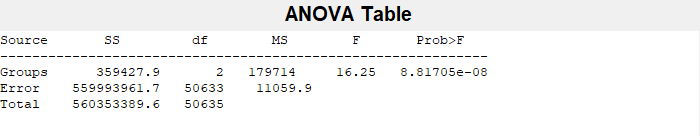

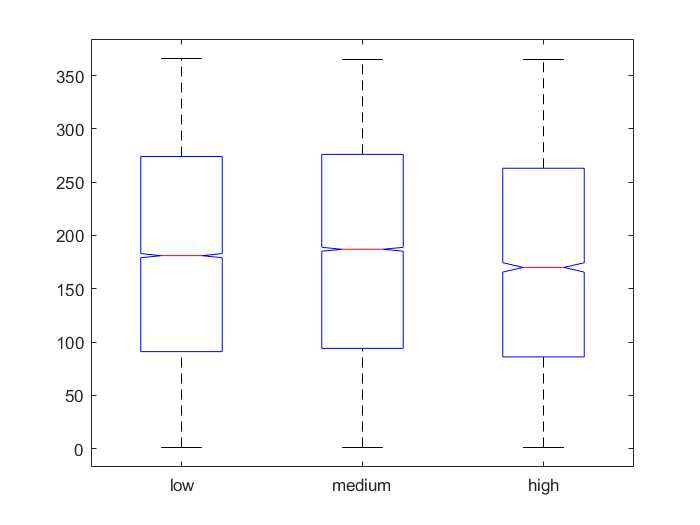

p = 8.8170e-08

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'   }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[3.5943e+05]}    {[    2]}    {[1.7971e+05]}    {[ 16.2492]}    {[8.8170e-08]}
    {'Error' }    {[5.5999e+08]}    {[50633]}    {[1.1060e+04]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[5.6035e+08]}    {[50635]}    {0×0 double  }    {0×0 double}    {0×0 double  }



[p,tbl]=anova1(df.dayofyear,df.demand)

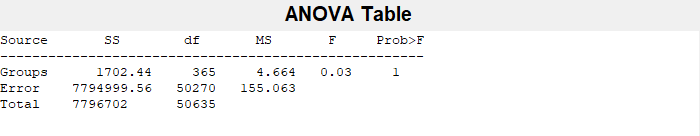

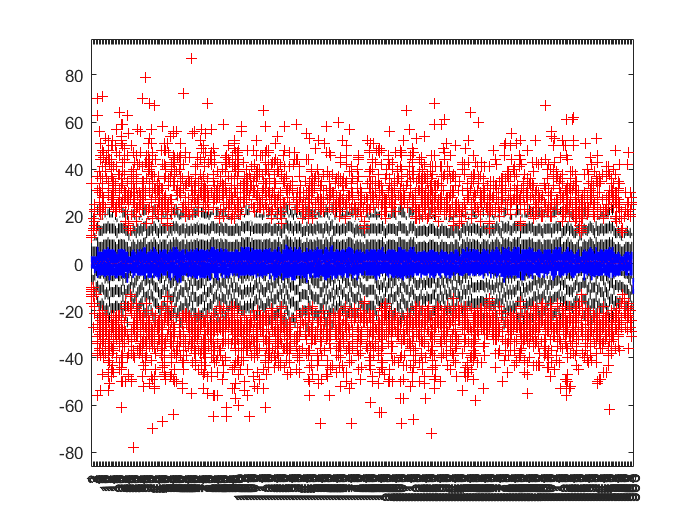

p = 1

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'   }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[1.7024e+03]}    {[  365]}    {[  4.6642]}    {[  0.0301]}    {[       1]}
    {'Error' }    {[7.7950e+06]}    {[50270]}    {[155.0627]}    {0×0 double}    {0×0 double}
    {'Total' }    {[   7796702]}    {[50635]}    {0×0 double}    {0×0 double}    {0×0 double}



[p,tbl]=anova1(df.netpickups,df.dayofyear)


%[p,tbl]=anova1(string(df.demand),df.dayofyear)

%df_2= isholiday(df,holidays)

%[a,chi2,p]=crosstab(df_2.demand,df_2.isholiday)

%[a,chi2,p]=crosstab(df_2.demand,df_2.DayOfWeek)

%s=groupsummary(df_2,["DayOfWeek","region"],"mean","netpickups")

%gscatter(s.DayOfWeek,s.region,s.mean_netpickups)

%heatmap(s,"DayOfWeek","mean_netpickups")

%df_2.hourofday=hours(timeofday(df_2.hourly_data))

%corr(df_2.demand,df_2.avg_duration)

%df_3=df_2

%df_3.demand(df_2.demand=='low')=0

%df_3.demand=grp2idx(df_3.demand)

%summary(df_3)

%corr(df_3.demand,df_3.avg_duration)

%corr(df_3.demand,df_3.avg_distance)

%corr(df_3.demand,df_3.avg_fare)

%corr(df_3.demand,df_3.DayOfWeek)

### Raw Model

### Oversampling the Minority Class

### Prediction on Test Data

### Classifier Function

### Loss analysis